# Sample 9-5

## 離散ウェーブレット変換

インプレース実装

画像処理特論

村松 正吾 

動作確認: MATLAB R2020a

## Discrete wavelet transform

Inplace implementation

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2020a

### 準備

(Preparation)

close all

## 入力信号の生成

(Generation of input)

% Input signal
u = rand(64,1);% [ 0 3 1 3 1 5 3 0 ]; % Set to even length

### 9/7-DWTインプレース実装

(Inplace implementation of 9/7 DWT)

以下の関数を利用。定義は末尾に添付。(The following functions are used. Definitions are attached at the end.)

- TRANS97: Inplace implementation of forward 9/7-transform.

- ITRANS97: Inplace implementation of inverse 9/7-transform.

対称拡張法による境界処理も適用。(The symmetric extension method is also applied as the boundary processing.)

% 3-level hierachical analysis process
[s10,s11] = trans97(u);
[s20,s21] = trans97(s10);
[s30,s31] = trans97(s20);

% 3-level hierachical synthesis process
v2 = itrans97(s30,s31);
v1 = itrans97(v2,s21);
v  = itrans97(v1,s11);

## 信号表示

(Signal display)

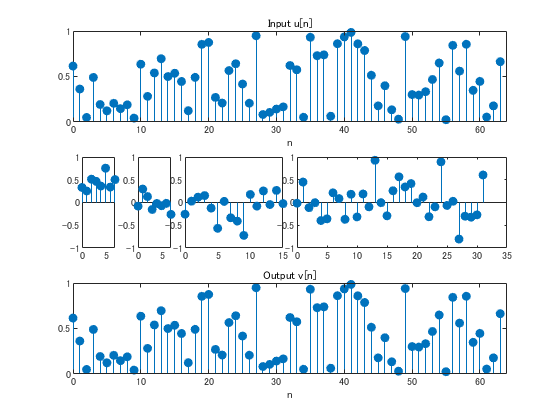

figure(1)
% Input
subplot(3,8,[1,8])
stem(0:length(u)-1,u,'filled')
title('Input u[n]')
xlabel('n')
ax = gca;
ax.XLim =[ 0 length(u)];

% Subband 30
subplot(3,8,9)
stem(0:length(s30)-1,s30,'filled')
ax = gca;
ax.YLim =[ -1 1 ];

% Subband 31
subplot(3,8,10)
stem(0:length(s31)-1,s31,'filled')
ax = gca;
ax.YLim =[ -1 1 ];

% Subband 21
subplot(3,8,[11,12])
stem(0:length(s21)-1,s21,'filled')
ax = gca;
ax.YLim =[ -1 1 ];

% Subband 11
subplot(3,8,[13,16])
stem(0:length(s11)-1,s11,'filled')
ax = gca;
ax.YLim =[ -1 1 ];

% Output
subplot(3,8,[17,24])
stem(0:length(v)-1,v,'filled')
title('Output v[n]')
xlabel('n')
ax = gca;
ax.XLim =[ 0 length(v)];

### インパルス応答（局所基底ベクトル）

(Impluse responses of synthesis filters; local basis vectors)

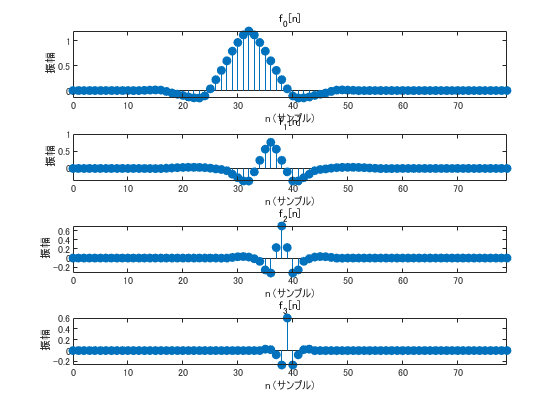

% 3-level hierachical synthesis process
f = cell(4,1);
for idx = 1:4
    s30 = zeros(10,1);
    s31 = zeros(10,1);
    s21 = zeros(20,1);
    s11 = zeros(40,1);
    if idx == 1
        s30(ceil(end/2)) = 1;
    elseif idx == 2
        s31(ceil(end/2)) = 1;
    elseif idx == 3
        s21(ceil(end/2)) = 1;
    else
        s11(ceil(end/2)) = 1;
    end
    v2 = itrans97(s30,s31);
    v1 = itrans97(v2,s21);
    f{idx}  = itrans97(v1,s11);
end

figure(2)
subplot(4,1,1)
impz(f{1})
title('f_0[n]')
subplot(4,1,2)
impz(f{2})
title('f_1[n]')
subplot(4,1,3)
impz(f{3})
title('f_2[n]')
subplot(4,1,4)
impz(f{4})
title('f_3[n]')

### 周波数応答

(Frequency responses)

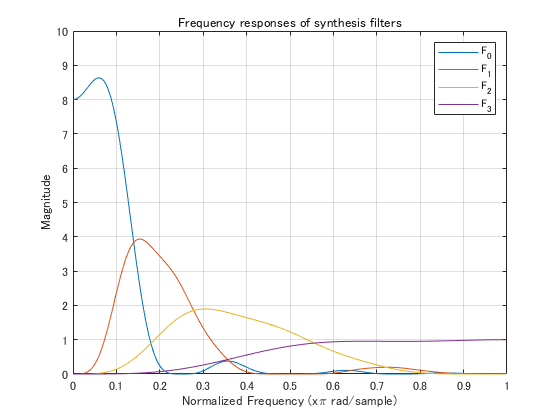

figure(3)
fftPoints = 512;
F = zeros(fftPoints,4);
for idx = 1:4
    if idx == 1
        [F(:,idx),W] = freqz(f{idx},1,fftPoints);
    else
        F(:,idx)     = freqz(f{idx},1,fftPoints);
    end
end
plot(W/pi, abs(F)) %20*log10(abs(F)))
axis([0 1 0 10]) %-70 10])
xlabel('Normalized Frequency (x\pi rad/sample)')
ylabel('Magnitude') % (dB)')
title('Frequency responses of synthesis filters')
legend({'F_0','F_1','F_2','F_3'})
grid on

### 関数定義

(Function definition)

Forward 9/7-transform w/ inplace implementation

function [subL,subH] = trans97(seq)
%
% Copyright (C) 2005-2015 Shogo MURAMATSU, All rights reserved
%
alpha = -1.586134342059924;
beta  = -0.052980118572961;
gamma =  0.882911075530934;
delta =  0.443506852043971;
K =  1.230174104914001;

seq = double(seq);

% Inplace implementation
seq = inplaceprediction(seq,alpha);
seq = inplaceupdate(seq,beta);
seq = inplaceprediction(seq,gamma);
seq = inplaceupdate(seq,delta);
seq(1:2:end) = seq(1:2:end)/K;
seq(2:2:end) = seq(2:2:end)*K;

% Split coefficients
subL = seq(1:2:end);
subH = seq(2:2:end);

end

Inverse 9/7-transform w/ inplace implementation

function seq = itrans97(subL,subH)
%
% Copyright (C) 2005-2015 Shogo MURAMATSU, All rights reserved
%
alpha = -1.586134342059924;
beta  = -0.052980118572961;
gamma =  0.882911075530934;
delta =  0.443506852043971;
K =  1.230174104914001;

% Preparation
fulllength = length(subL) + length(subH);
seq = zeros(fulllength,1);

% Mearge coefficients
seq(1:2:end) = subL;
seq(2:2:end) = subH;

% Inplace implementation
seq(1:2:end) = seq(1:2:end)*K;
seq(2:2:end) = seq(2:2:end)/K;
seq = inplaceupdate(seq,-delta);
seq = inplaceprediction(seq,-gamma);
seq = inplaceupdate(seq,-beta);
seq = inplaceprediction(seq,-alpha);
end

Prediction lifting step w/ inplace implementation

function seq = inplaceprediction(seq,p)
%
% Copyright (C) 2020 Shogo MURAMATSU, All rights reserved
%
flagrow = isrow(seq);
if flagrow
    seq = seq.';
end

if (mod(length(seq),2)==0)
    seq(2:2:end) = seq(2:2:end) ... % Symmetric extension at the boundary
        + p * ( seq(1:2:end) + [seq(3:2:end);seq(end-1)]);
else
    seq(2:2:end) = seq(2:2:end) ...
        + p * (seq(1:2:end-2) + seq(3:2:end));
end
if flagrow
    seq = seq.';
end
end

Update lifting step w/ inplace implementation

function seq = inplaceupdate(seq,u)
%
% Copyright (C) 2020 Shogo MURAMATSU, All rights reserved
%
flagrow = isrow(seq);
if flagrow
    seq = seq.';
end
if (mod(length(seq),2)==0)
    seq(1:2:end) = seq(1:2:end) ...
        + u * ( [seq(2); seq(2:2:end-1)] + seq(2:2:end));
else
    seq(1:2:end) = seq(1:2:end) ... % Symmetric extension at the boundary
        + u * ( [seq(2); seq(2:2:end-1)] + [seq(2:2:end); seq(end-1)]);
end
if flagrow
    seq = seq.';
end
end

© Copyright, Shogo MURAMATSU, All rights reserved.